**MNIST**

Read `mnist_train.csv`, create a dataframe with two columns, column `feature` contains all 𝑥 and column `label` contains all 𝑦.

Plot the first 30 images.

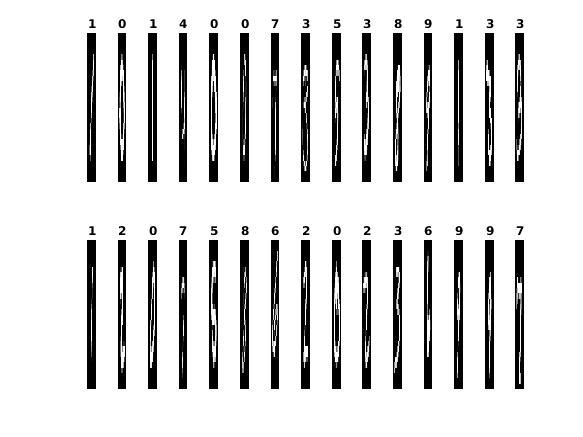

% Load data and avoid reloading every time
    if ~exist('mnist_load','var')
        mnist = csvread('mnist_train.csv', 1, 0);
        mnist_load=1;
    end

%Plot first 30 samples 
figure
colormap(gray);
for i = 1:30
    subplot(2, 15, i);
    digit = reshape(mnist(i, 2:end),[28,28])';
    imagesc(digit);    axis off;
    title(num2str(mnist(i,1)));
end

**Example 2.1**

When 𝑛=1, we can fit a degree-𝑚 polynomial by choosing 𝑓𝑗(𝑥)=𝑥𝑗−1 and 𝑀=𝑚+1. In this case, it follows that 𝐴𝑖,𝑗=𝑥𝑗−1𝑖 and the matrix 𝐴 is called a Vandermonde matrix.

Write a function to create Vandermonde matrix **(5 pt)**

%% Problem 2.1
    % When $n=1$, we can fit a degree-$m$ polynomial by choosing 
    % $f_j(x)=x^{j-1}$ and $M=m+1$. In this case, it follows that 
    % $A_{i,j}=x_{i}^{j-1}$ and the matrix $A$ is called a Vandermonde 
    % matrix.
    %
    % Write a function to create Vandermonde matrix **(5pt)**
    fprintf('\nProblem 2.1\n')


Problem 2.1


    fprintf('Vandermonte matrix for 1:10 up to degree 3 is\n')

Vandermonte matrix for 1:10 up to degree 3 is


    disp(create_vandermonde(1:10, 3))

           1           1           1           1
           1           2           4           8
           1           3           9          27
           1           4          16          64
           1           5          25         125
           1           6          36         216
           1           7          49         343
           1           8          64         512
           1           9          81         729
           1          10         100        1000



**Exercise 2.2**

Write a function to solve least-square problem via linear algebra **(5 pt)**

Using the setup in the previous example, try fitting the points (1,2),(2,3),(3,5),(4,7),(5,11),(6,13)(1,2),(2,3),(3,5),(4,7),(5,11),(6,13) to a degree-2 polynomial.

Compute the minimum squared error. **(5 pt)**

Plot this polynomial (for 𝑥∈[0,7]) along with the data points to see the quality of fit. **(5 pt)**

%% Problem 2.2
    % Write a function to solve least-square problem **(5pt)**
    % Using the setup in the previous example, try fitting the points 
    % (1,2),(2,3),(3,5),(4,7),(5,11),(6,13) to a degree-2 polynomial.
    % 
    % Compute the minimum squared error. **(5pt)**
    % 
    % Plot this polynomial (for $x\in[0,7]$) along with the data points to 
    % see the quality of fit. **(5pt)**
    fprintf('\nProblem 2.2\n')


Problem 2.2


    x = [1, 2, 3, 4, 5, 6]'; %inut data
    y = [2, 3, 5, 7, 11, 14]'; %output data
    m = 2;
    
    A = create_vandermonde(x, m); %create input data vandermonde matrix
    z_hat = solve_linear_LS(A, y); 
    N = size(z_hat,2);
    mse = 1/N*sum((A*z_hat - y).^2);% ### compute the minimum squared error
    result = sprintf('polynomial fit is %.4f x^2 + %.4f x + %.4f, mse = %.4f', ...
        z_hat(3), z_hat(2), z_hat(1), mse); 
    disp(result)                             

polynomial fit is 0.3214 x^2 + 0.2071 x + 1.4000, mse = 0.4857


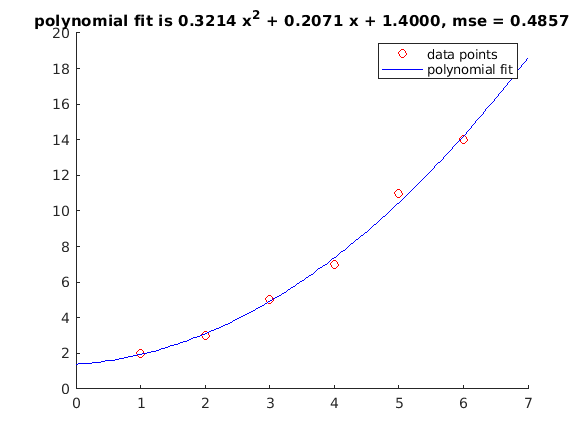

    
    xx = linspace(0,7);% ### generate x values for plotting fitted polynomial
    yy = z_hat(3).*xx.^2+z_hat(2).*xx+z_hat(1);% ### generate y values for plotting fitted polynomial
    
    figure
    hold on
    scatter(x, y, 'ro')
    plot(xx, yy, 'b-')
    legend('data points', 'polynomial fit')
    title(result)
    hold off

% Use gradient descent to solve least-squares problem and minimize || y - A z2 ||^2
    fprintf('\nProblem 2.3\n')


Problem 2.3


**Exercise 2.3**

Write a function to solve a least-squares problem via gradient descent. **(5 pt)**

Compute the minimum squared error. **(5 pt)**

Plot the resulting polynomial (for 𝑥∈[0,7]) along with previous polynomial and original data points to see the quality of fit. **(5 pt)**

step = 0.0002;
    niter = 100000; %set the step size and iteration times
    z2_hat = solve_linear_LS_gd(A,y,step,niter);  %use gradient decent to find the z vector
% Compute the minimum square error
    mse2 = 1/N*sum((A*z2_hat - y).^2);
    result2 = sprintf('polynomial fit is %.4f x^2 + %.4f x + %.4f, mse = %.4f', ...
    z2_hat(3), z2_hat(2), z2_hat(1), mse2);
    disp(result2)

polynomial fit is 0.2835 x^2 + 0.5005 x + 0.9509, mse = 0.5529


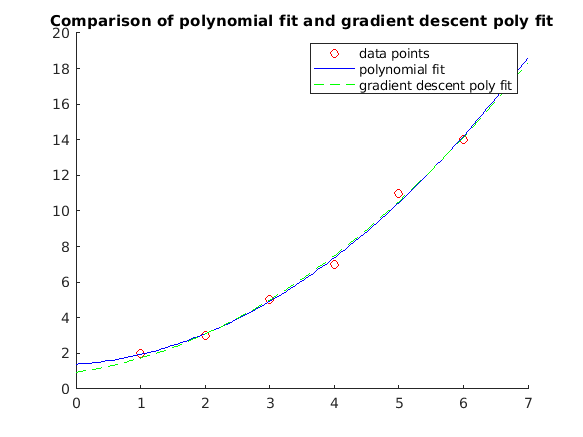

% Generate y plot points for the gd fitted polynomial
    yy2 = z2_hat(3).*xx.^2+z2_hat(2).*xx+z2_hat(1);
    figure
    hold on
    scatter(x, y, 'ro')
    plot(xx, yy, 'b-')
    plot(xx, yy2, 'g--')  %plot the gradient decent polynomial curve on previous one to compare
    legend('data points', 'polynomial fit', 'gradient descent poly fit')
    title('Comparison of polynomial fit and gradient descent poly fit')
    hold off

**Exercise 3.2**

Write the function `extract_and_split` to extract the all samples labeled with digit 𝑛n and randomly separate fraction of samples into training and testing groups. **(10 pt)**

Pairwise experiment for applying least-square to classify digit 𝑎 and digit 𝑏.

Follow the given steps in the template and implement the function for pairwise experiment **(15 pt)**

%% Problem 3.2
    % Extract the all samples labeled with digit $d$ and randomly separate 
    % the samples into equal-sized training and testing groups. **(10pt)**
    % Pairwise experiment for applying least-square to classify digit a, b
    % Follow the given steps in the template and implement the function for 
    % pairwise experiment **(25pt)**
    fprintf('\nProblem 3.2\n')


Problem 3.2


Pairwise experiment, mapping 0 to -1, mapping 1 to 1
training error = 0.34%, testing error = 0.88%
Confusion matrix of training sets:
        2062           4
          11        2331

Confusion matrix of test sets:
        2052          14
          25        2317



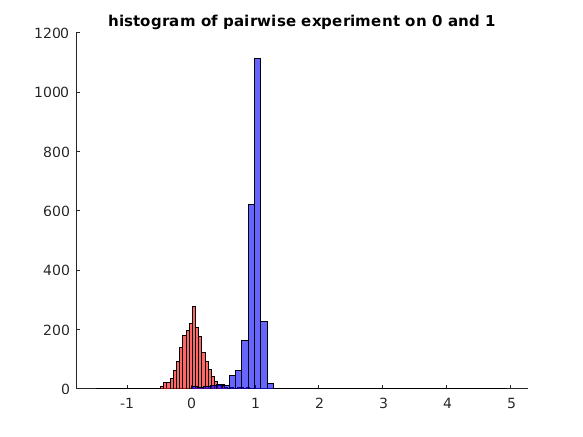

    mnist_pairwise_LS(mnist, 0, 1, 0.5, true); %notice that the imput matrix is not full rank and I didn't supress warning

Notice that in this problem I also tried to call the gradient decent to do this binary classification task. However the resesult it pretty bad  so I didn't

plot the result here. I think that indicate the initial state and step length are so important for gradient decent. That if we change these parameters

the performance of the function will change alot for a specific problem so we have to try or according to out empirical knowledge to find the optimal

parameters.

**Exercise 3.3**

Repeat the above problem for all pairs of digits. For each pair of digits, report the classification error rates for the training and testing sets. The error rates can be formatted nicely into a triangular matrix. Put testing error in the lower triangle and training error in the upper triangle.

The code is given here in order demonstrate tqdm. Points awarded for reasonable values **(10 pt)**

%% Problem 3.3
    % Repeat the above problem for all pairs of digits. For each pair of 
    % digits, report the classification error rates for the training and 
    % testing sets. The error rates can be formatted nicely into a 
    % triangular matrix. **(15pt)**
    %
    % For example, you can put all testing error in the lower triangle and 
    % all training error in the upper triangle.
    % You may run the classification several times to get an average error 
    % rate over different sample split.
    fprintf('\nProblem 3.3\n')


Problem 3.3


    num_trial = 1;
    if exist('errMat.csv','file')
        err_Matrix = readmatrix('errMat.csv'); %I have previously store the err matrix into a .csvfile considering that
                                               %running time of it is extemely
                                               %long in matlab.
                                               
    else
        err_Matrix_store = zeros(10); %if it is the first time that we run this code we will compute the matrix
        for w = 1:num_trial
            err_Matrix = zeros(10);
            for i = 1:9
                for j = i+1:10
                    midvector = mnist_pairwise_LS(mnist, i-1, j-1, 0.5, false); %we call the function 45 times
                    err_Matrix(i,j) = midvector(1); %store training err in upper triangle
                    err_Matrix(j,i) = midvector(2); %store testing err in lower triangle
                end
            end
            err_Matrix_store = err_Matrix_store +err_Matrix;  %we add matrix together after each trial
        end
        err_Matrix = err_Matrix_store./num_trial;  %get the average err matrix of all the trial not important
    end                                            %here because we have only one trial
    
    fprintf('The error matrix is\n')

The error matrix is


    disp(err_Matrix)

         0    0.3400    0.7700    0.4500    1.2700    0.7100    0.6000    0.2600    0.5600    0.2600
    1.1300         0    1.2000    0.6200    0.1800    0.5400    0.1100    0.5100    2.2200    0.3600
    2.1200    2.7500         0    2.2500    0.7500    1.5100    0.7000    0.8900    2.0400    0.7200
    1.6300    2.0100    4.8800         0    0.4000    2.9700    0.3300    1.0300    2.8100    1.3600
    2.2200    0.8900    2.8600    1.5200         0    0.5600    0.5100    1.2700    0.4400    2.4200
    2.2200    2.0800    3.3900    5.3800    1.8300         0    2.2700    0.2700    4.4700    0.9300
    1.9100    1.1600    3.2700    1.7000    1.5300    4.1800         0    0.0500    1.1200    0.2200
    0.8900    1.5200    3.0100    2.9900    2.7600    1.6100    1.1000         0    0.6600    3.0500
    1.7100    3.8400    4.2000    6.4600    1.6000    7.1500    2.5800    2.2400         0    1.1900
    1.3900    1.5300    2.1300    3.0000    5.0400    2.3500    0.7400    5.8900    3.4200 

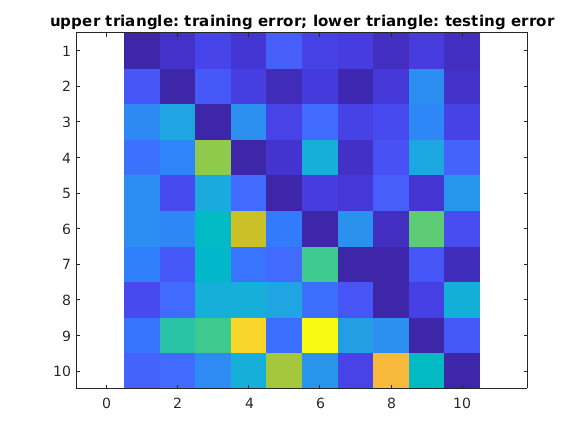

    figure
    imagesc(err_Matrix)
    axis('equal')
    title('upper triangle: training error; lower triangle: testing error')  

**Exercise 3.4**

But, what about a multi-class classifier for MNIST digits? For multi-class linear classification with d classes, one standard approach is to learn a linear mapping 𝑓:ℝ𝑛→ℝwhere the “𝑦”-value for the 𝑖i-th class is chosen to be the standard basis vector 𝑒⎯⎯𝑖∈ℝ𝑑. This is sometimes called one-hot encoding. Using the same 𝐴A matrix as before and a matrix 𝑌, defined by 𝑌𝑖,𝑗 if observation 𝑖 in class 𝑗 and 𝑌𝑖,𝑗=0 otherwise, we can solve for the coefficient matrix 𝑍∈ℝ𝑑 coefficients . Then, the classifier maps a vector 𝑥⎯⎯ to class 𝑖 if the 𝑖-th element of 𝑍𝑇𝑥⎯⎯ is the largest element in the vector.

Follow the steps in the template and implement the multi-class classification experiment **(20 pt)**

%% Problem 3.4
    % But, what about a multi-class classifier for MNIST digits? 
    % For multi-class linear classification with d classes, one standard 
    % approach is to learn a linear mapping f: R^n -> R^d where the 
    % ?$y$?-value for the $i$-th class is chosen to be the standard basis 
    % vector $ \underline{e}_i \in \mathbb{R}^d $. 
    % This is sometimes called one-hot encoding. 
    % Using the same $A$ matrix as before and a matrix $Y$, defined by 
    % $Y_{i,j}$ if observation $i$ in class $j$ and $Y_{i,j} = 0$ otherwise, 
    % we can solve for the coefficient matrix $Z \in R^d$ coefficients .
    % Then, the classifier maps a vector $\underline{x}$ to class $i$ if 
    % the $i$-th element of $Z^T \underline{x}$ is the largest element in 
    % the vector. 
    % 
    % Follow the given steps in the template and implement the function for 
    % multi-class classification experiment **(30pt)**
    fprintf('\nProblem 3.4\n')


Problem 3.4


training error = 13.29%, testing error = 15.27%
Confusion matrix:
        1966           6           8           3          13          18          26           4          20           2
           1        2272          17           8           7           6           9           2          18           2
          32          92        1641          57          49           9          94          36          67          11
          17          58          75        1798          13          61          19          41          50          43
           3          37          21           1        1796          23          17          10          18         110
          74          43          12         142          45        1365          69          17          73          57
          46          28          21           0          34          33        1899           0           7           0
          18          70          16          13          73           6           4   

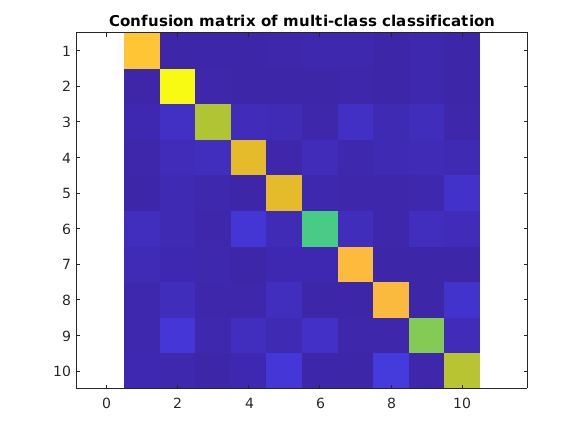

    mnist_onehot_LS(mnist, 0.5);

Below are implementation of functions

function A = create_vandermonde(x, m)
% Arguments:
%     x -- 1d-array of (x_1, x_2, ..., x_n)
%     m -- a non-negative integer, degree of polynomial fit
% Returns:
%     A -- an n x (m+1) matrix where A_{ij} = x_i^{j-1}
nget = size(x,2);
if nget ~= 1      %if the input is not a column vector we transpose it
    x = x';
end
n = size(x,1);
A = ones(n,1);
for i = 1:m
    A = [A x.^i]; % we concate the nth exponential of x each time to get vandermonde matrix
end
end

function z_hat = solve_linear_LS(A, y)
% Arguments:
%     A -- an m x n matrix
%     y -- an n x d matrix
% Returns:
%     z_hat -- m x d matrix, LS solution
z_hat = A\y;    %incase A is not full rank
end

function z_hat = solve_linear_LS_gd(A,y,step,niter)
    len = size(A,1);
    wid = size(A,2);
    z_hat = zeros(wid,1);
    for i = 1:niter   %update z_hat each time according to partial cyclic gradient decent
        z_hat = z_hat + step.*(y(mod(i,len)+1)-A(mod(i,len)+1,:)*z_hat).*(A(mod(i,len)+1,:))';
    end
% Arguments:
%     A -- an m x n matrix
%     y -- an n x d matrix
%     step -- a floating point number, step size
%     niter -- a non-negative integer, number of updates
% Returns:
%     z_hat -- m x d matrix, LS solution
end

function [X_tr, X_te, y_tr, y_te] = extract_and_split(mnist, d, test_size)
% extract the samples with given lables and randomly separate the samples 
% into equal-sized training and testing groups, extend each vector to 
% length 785 by appending a ?1
% Arguments:
%     mnist -- the MNIST data set read from csv file
%     d -- digit needs to be extracted, can be 0, 1, ..., 9
%     test_size -- the fraction of testing set
% Returns:
%     X_tr -- training set features, a matrix with 785 columns
%             each row corresponds the feature of a sample
%     y_tr -- training set labels, 1d-array
%             each element corresponds the label of a sample
%     X_te -- testing set features, a matrix with 785 columns 
%             each row corresponds the feature of a sample
%     y_te -- testing set labels, 1d-array
%             each element corresponds the label of a sample
storage = zeros(1,size(mnist,2)); %extract all lines of data of d from mnist
k = 1;
for i = 1:size(mnist,1)
    if mnist(i,1) == d
        for j = 1:size(mnist,2)
            storage(k,j) = mnist(i,j);
        end
        k = k+1;
    end
end
extend = [storage, -ones(size(storage,1),1)];  %extend the data by appening -1 to the end so the hyperplane does not
                                               %need to across original
                                               %point
idx = randperm(size(extend,1));                %to generate random numbers
X_tr = extend(idx(1:floor(test_size*size(extend,1))),2:end);
X_te = extend(idx(round(test_size*size(extend,1))+1:end),2:end);  %id it is odd number then we discard one in the midde
y_tr = extend(idx(1:floor(test_size*size(extend,1))),1);  % first column store the label
y_te = extend(idx(round(test_size*size(extend,1))+1:end),1);
    
end

function x_filtered = remove_outlier(x)
% returns points that are not outliers to make histogram prettier
% reference: https://stackoverflow.com/questions/11882393/matplotlib-disregard-outliers-when-plotting/11886564
% Arguments:
%     x -- 1d-array, points to be filtered
% Returns:
%     x_filtered -- 1d-array, filtered points after dropping outlier
    modified_z_score = 0.6745 * abs(x - median(x));
    x_filtered = x(modified_z_score <= 3.5);
end

function [err_tr, err_te] = mnist_pairwise_LS(mnist, a, b, test_size, verbose)
% Pairwise experiment for applying least-square to classify digit a, b
% Arguments:
%     mnist -- the MNIST data set read from csv file
%     a, b -- digits to be classified
%     test_size -- the fraction of testing set
%     verbose -- whether to print and plot results
% Returns:
%     err_tr -- training set classification error
%     err_te -- testing set classification error

    % Find all samples labeled with digit a and split into train/test sets
    [Xa_tr, Xa_te, ya_tr, ya_te] = extract_and_split(mnist, a, test_size);
    
    % Find all samples labeled with digit b and split into train/test sets
    [Xb_tr, Xb_te, yb_tr, yb_te] = extract_and_split(mnist, b, test_size);
    
    % Construct the full training set
    X_tr = [Xa_tr; Xb_tr];
    y_tr = [ya_tr; yb_tr];
    
    %We map lable a to 1 and b to -1 to improve the classifcation result
    y_tr_optimized = [-ones(size(ya_tr,1),1); ones(size(yb_tr,1),1)];
    
    % Construct the full testing set
    X_te = [Xa_te; Xb_te];
    y_te = [ya_te; yb_te]; 
    
    % Run least-square on training set
    z_hat = X_tr\y_tr_optimized;
    
    % Compute estimation and misclassification on training set
    y_hat_tr = X_tr*z_hat;
    for i = 1:size(y_hat_tr,1)
        if y_hat_tr(i) >= 0
            y_hat_tr(i) = b;
        else
            y_hat_tr(i) = a;
        end
    end
    
    count = 0;
    for j = 1:size(y_hat_tr,1)
        if y_hat_tr(j) ~= y_tr(j)
            count = count +1;
        end
    end
    err_tr = count/size(y_tr,1);
    
    % Compute estimation and misclassification on testing set
    y_hat_te = X_te*z_hat;
    for k = 1:size(y_hat_te,1)
        if y_hat_te(k) >= 0
            y_hat_te(k) = b;
        else
            y_hat_te(k) = a;
        end
    end
    
    count_te = 0;
    for l = 1:size(y_hat_tr,1)
        if y_hat_te(l) ~= y_te(l)
            count_te = count_te +1;
        end
    end
    err_te = count_te/size(y_te,1) ;
    
    if verbose
        fprintf('Pairwise experiment, mapping %d to -1, mapping %d to 1\n', a, b)
        fprintf('training error = %.2f%%, testing error = %.2f%%\n', 100 * err_tr, 100 * err_te)
        
        % Compute confusion matrix
        cm_tr = confusionmat(y_tr, y_hat_tr);
        fprintf('Confusion matrix of training sets:\n')
        disp(cm_tr)
        fprintf('Confusion matrix of test sets:\n')
        cm_te = confusionmat(y_te, y_hat_te);
        disp(cm_te)
        % Compute the histogram of the function output separately for each 
        % class, then plot the two histograms together
        y_hat_primary = X_te*z_hat;
        ya_te_hat = [0];
        yb_te_hat = [0];
        count2 = 1;
        count3 = 1;
        for m = 1:size(y_hat_primary,1)  % count the number of a's and b's
            if y_hat_primary(m) < 0
                ya_te_hat(1,count2) = y_hat_primary(m);
                count2 = count2 + 1;
            else
                yb_te_hat(1,count3) = y_hat_primary(m);
                count3 = count3 + 1;
            end
        end
        
        ya_te_hat = ya_te_hat+(a+1);  %we have to restore a b from -1 and 1
        yb_te_hat = yb_te_hat+(b-1);
        % Remove outlier to make pretty histogram
        ya_te_hat = remove_outlier(ya_te_hat);
        yb_te_hat = remove_outlier(yb_te_hat);
        
        figure
        hold on
        histogram(ya_te_hat, 50, 'facecolor', 'red')
        histogram(yb_te_hat, 50, 'facecolor', 'blue')
        title(sprintf('histogram of pairwise experiment on %d and %d', a, b))
    end
end

function [err_tr, err_te] = mnist_onehot_LS(mnist, test_size)
% Experiment for applying least-square to classify all digits using one-hot 
% encoding
% Arguments:
%     mnist -- the MNIST data set read from csv file
%     test_size -- the fraction of testing set
% Returns:
%     err_tr -- training set classification error
%     err_te -- testing set classification error
    % Split into training/testing set
    [X0_tr, X0_te, y0_tr, y0_te] = extract_and_split(mnist, 0, test_size);
    [X1_tr, X1_te, y1_tr, y1_te] = extract_and_split(mnist, 1, test_size);
    [X2_tr, X2_te, y2_tr, y2_te] = extract_and_split(mnist, 2, test_size);
    [X3_tr, X3_te, y3_tr, y3_te] = extract_and_split(mnist, 3, test_size);
    [X4_tr, X4_te, y4_tr, y4_te] = extract_and_split(mnist, 4, test_size);
    [X5_tr, X5_te, y5_tr, y5_te] = extract_and_split(mnist, 5, test_size);
    [X6_tr, X6_te, y6_tr, y6_te] = extract_and_split(mnist, 6, test_size);
    [X7_tr, X7_te, y7_tr, y7_te] = extract_and_split(mnist, 7, test_size);
    [X8_tr, X8_te, y8_tr, y8_te] = extract_and_split(mnist, 8, test_size);
    [X9_tr, X9_te, y9_tr, y9_te] = extract_and_split(mnist, 9, test_size);
    % Construct the training set
    X_tr = [X0_tr; X1_tr; X2_tr; X3_tr; X4_tr; X5_tr; X6_tr; X7_tr; X8_tr; X9_tr];
    y_tr = [y0_tr; y1_tr; y2_tr; y3_tr; y4_tr; y5_tr; y6_tr; y7_tr; y8_tr; y9_tr];
    
    % Construct the testing set
    X_te = [X0_te; X1_te; X2_te; X3_te; X4_te; X5_te; X6_te; X7_te; X8_te; X9_te];
    y_te = [y0_te; y1_te; y2_te; y3_te; y4_te; y5_te; y6_te; y7_te; y8_te; y9_te];
    
    % Apply one-hot encoding to training labels
    Y = zeros(size(y_tr,1),10);
    for i = 1:size(y_tr,1)
        Y(i,y_tr(i,1)+1) = 1;
    end
    % Run least-square on training set
    Z = X_tr\Y;
    
    % Compute estimation and misclassification on training set
    y_hat_tr_hot = X_tr*Z;
    y_hat_tr = zeros(size(y_hat_tr_hot,1),1);
    for j = 1:size(y_hat_tr_hot,1)
        [~,n] = max(y_hat_tr_hot(j,:));
        y_hat_tr(j,1) = n-1;
    end
    count = 0;
    for k = 1:size(y_hat_tr,1)
        if y_hat_tr(k) ~= y_tr(k)  %if the output doesn't match the lable we call it a error
            count = count +1;
        end
    end
    err_tr = count/size(y_tr,1);  %compute the err rate
    
    % Compute estimation and misclassification on training set
    y_hat_te_hot = X_te*Z;
    y_hat_te = zeros(size(y_hat_te_hot,1),1);
    for l = 1:size(y_hat_te_hot,1)
        [~,m] = max(y_hat_te_hot(l,:));
        y_hat_te(l,1) = m-1;
    end
    count_te = 0;
    for o = 1:size(y_hat_te,1)
        if y_hat_te(o) ~= y_tr(o)
            count_te = count_te +1;
        end
    end
    err_te = count_te/size(y_te,1);
    
    fprintf('training error = %.2f%%, testing error = %.2f%%\n', 100 * err_tr, 100 * err_te)
    % Compute confusion matrix
    cm = confusionmat(y_te, y_hat_te);  %generate the confusion matrix
    fprintf('Confusion matrix:\n')
    disp(cm)
    figure
    imagesc(cm)
    axis('equal')
    title('Confusion matrix of multi-class classification')
end
